`Part 1: Berry Esseen Implementation`

N = 2; %Dimension of the functions considered
M = 10^3;
n = 50; %time stepping schemes number of points
c_alpha = 1.96;
C_BE = 30.51175;
function_name = 'Oscillator';

I_ex = exact_ref_solutions(function_name, N);

estimates = zeros([1 M]);
variances = zeros([1 M]);
exact_err = zeros([1 M]);
stat_err = zeros([1 M]);
BE_bound = zeros([1 M]);

for k=1:M
    rng(2)
    if function_name == 'Oscillator'
        [estimates(k), variances(k)] = Monte_Carlo_HW1(@f_Oscillatory, N, k);
    end
    exact_err(k) = abs(estimates(k) - I_ex);
end

% 3rd moment estimation
M_BE = 10^3;
samples3rdmoment = rand(N, M_BE); 
if function_name == 'Oscillator'     
    Y = f_Oscillatory(samples3rdmoment);
    [estimate, variance] = Monte_Carlo_HW1(@f_Oscillatory, N, M_BE);
end
thirdmoment = 1/(M_BE)*sum(abs(Y - estimate).^3); % MC estimate for 3rd moment
lambda = thirdmoment/variance^3;

syms var
%c0 = vpasolve(2*normcdf(var)-1-2*(C_BE*lambda)./((1+var)^3*sqrt(M_BE)) == 0.95, var);

% Error computations
for k=progress(1:M)
    c0 = vpasolve(2*normcdf(var)-1-2*(C_BE*lambda)./((1+var)^3*sqrt(k)) == 0.95, var);
    stat_err(k) = c_alpha*sqrt(variances(end))/sqrt(k);
    BE_bound(k) = c0*sqrt(variance(end))/sqrt(k);
    %BE_bound(k) = 2*normcdf(c0) - 1- 2*C_BE*lambda/((1+c0)^3*sqrt(k));
end

Processing:  000%  |                                    | 0/1000it [00:00:00<Inf:NaN:NaN, Inf it/s]


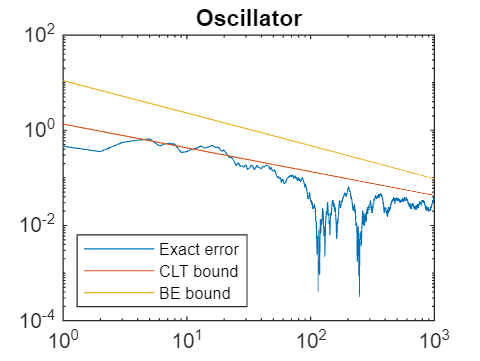


loglog(1:M, exact_err, 1:M, stat_err, 1:M, BE_bound)
legend('Exact error', 'CLT bound', 'BE bound', fontsize=7, location='southwest')
title(function_name)

savePDF("C:/git/UQ4PDE_Homeworks/Homework 1/Plots/Part 2/", "BE_bound_Osc_N2")